# Binaural Audio Rendering Using Head Tracking

Track head orientation by fusing data received from an IMU, and then control the direction of arrival of a sound source by applying head-related transfer functions (HRTF).

In a typical virtual reality setup, the IMU sensor is attached to the user's headphones or VR headset so that the perceived position of a sound source is relative to a visual cue independent of head movements. For example, if the sound is perceived as coming from the monitor, it remains that way even if the user turns his head to the side.

## Required Hardware

- Arduino Uno

- Invensense MPU-9250

## Hardware Connection

First, connect the Invensense MPU-9250 to the Arduino board. For more details, see [Estimating Orientation Using Inertial Sensor Fusion and MPU-9250](docid:fusion_ug#mw_8d78390d-55d2-47e8-a396-5c8217acad77). 

## Create Sensor Object and IMU Filter

Create an `arduino` object.

a = arduino;

Create the Invensense MPU-9250 sensor object.

imu = mpu9250(a);

Create and set the sample rate of the Kalman filter.

Fs = imu.SampleRate;
imufilt = imufilter('SampleRate',Fs);

## Load the ARI HRTF Dataset

When sound travels from a point in space to your ears, you can localize it based on interaural time and level differences (ITD and ILD). These frequency-dependent ITD and ILD's can be measured and represented as a pair of impulse responses for any given source elevation and azimuth. The ARI HRTF Dataset contains 1550 pairs of impulse responses which span azimuths over 360 degrees and elevations from -30 to 80 degrees. You use these impulse responses to filter a sound source so that it is perceived as coming from a position determined by the sensor's orientation. If the sensor is attached to a device on a user's head, the sound is perceived as coming from one fixed place despite head movements.

First, load the HRTF dataset.

ARIDataset = load('ReferenceHRTF.mat');

Then, get the relevant HRTF data from the dataset and put it in a useful format for our processing. 

hrtfData = double(ARIDataset.hrtfData);
hrtfData = permute(hrtfData,[2,3,1]);

Get the associated source positions. Angles should be in the same range as the sensor. Convert the azimuths from [0,360] to [-180,180].

sourcePosition = ARIDataset.sourcePosition(:,[1,2]);
sourcePosition(:,1) = sourcePosition(:,1) - 180;

## Load Monaural Recording

Load an ambisonic recording of a helicopter. Keep only the first channel, which corresponds to an omnidirectional recording. Resample it to 48 kHz for compatibility with the HRTF data set.

[heli,originalSampleRate] = audioread('Heli_16ch_ACN_SN3D.wav');
heli = 12*heli(:,1); % keep only one channel

sampleRate = 48e3;
heli = resample(heli,sampleRate,originalSampleRate);

Load the audio data into a `SignalSource` object. Set the `SamplesPerFrame` to `0.1` seconds.

sigsrc = dsp.SignalSource(heli, ...
    'SamplesPerFrame',sampleRate/10, ...
    'SignalEndAction','Cyclic repetition');

## Set Up the Audio Device

Create an `audioDeviceWriter` with the same sample rate as the audio signal.

deviceWriter = audioDeviceWriter('SampleRate',sampleRate);

## Create FIR Filters for the HRTF coefficients

Create a pair of FIR filters to perform binaural HRTF filtering.

FIR = cell(1,2);
FIR{1} = dsp.FIRFilter('NumeratorSource','Input port');
FIR{2} = dsp.FIRFilter('NumeratorSource','Input port');

## Initialize the Orientation Viewer

Create an object to perform real-time visualization for the orientation of the IMU sensor. Call the IMU filter once and display the initial orientation.

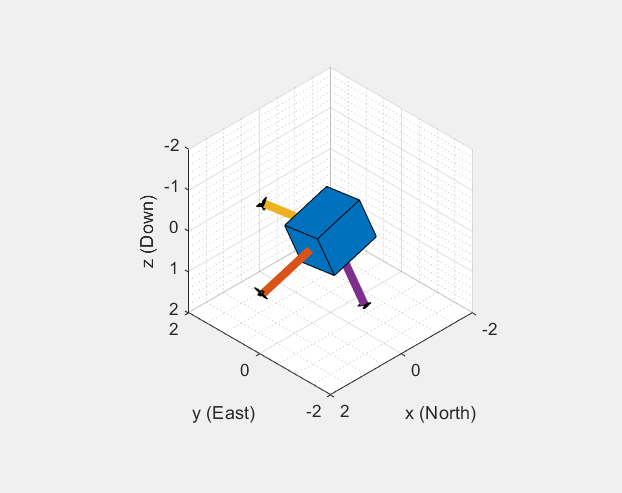

orientationScope = HelperOrientationViewer;
data = read(imu);

qimu = imufilt(data.Acceleration,data.AngularVelocity);
orientationScope(qimu);

[accel,gyro] = read(imu);

## Audio Processing Loop

Execute the processing loop for 30 seconds. This loop performs the following steps:

- Read data from the IMU sensor.

- Fuse IMU sensor data to estimate the orientation of the sensor. Visualize the current orientation.

- Convert the orientation from a quaternion representation to pitch and yaw in Euler angles.

- Use `interpolateHRTF` to obtain a pair of HRTFs at the desired position.

- Read a frame of audio from the signal source.

- Apply the HRTFs to the mono recording and play the stereo signal. This is best experienced using headphones.

imuOverruns = 0;
audioUnderruns = 0;
audioFiltered = zeros(sigsrc.SamplesPerFrame,2);
tic
while toc < 30

    % Read from the IMU sensor.
    [data,overrun] = read(imu);
    if overrun > 0
        imuOverruns = imuOverruns + overrun;
    end
    
    % Fuse IMU sensor data to estimate the orientation of the sensor.
    qimu = imufilt(data.Acceleration,data.AngularVelocity); 
    orientationScope(qimu);
    
    % Convert the orientation from a quaternion representation to pitch and yaw in Euler angles.
    ypr = eulerd(qimu,'zyx','frame');
    yaw = ypr(end,1);
    pitch = ypr(end,2);
    desiredPosition = [yaw,pitch];
    
    % Obtain a pair of HRTFs at the desired position.
    interpolatedIR = squeeze(interpolateHRTF(hrtfData,sourcePosition,desiredPosition));
    
    % Read audio from file   
    audioIn = sigsrc();
             
    % Apply HRTFs
    audioFiltered(:,1) = FIR{1}(audioIn, interpolatedIR(1,:)); % Left
    audioFiltered(:,2) = FIR{2}(audioIn, interpolatedIR(2,:)); % Right    
    audioUnderruns = audioUnderruns + deviceWriter(squeeze(audioFiltered)); 
end

## Cleanup

Release resources, including the sound device.

release(sigsrc)
release(deviceWriter)
clear imu a

*Copyright 2019 The MathWorks, Inc.*